PHYSICS 434 - APPLICATION OF COMPUTERS TO PHYSICAL MEASUREMENT

HOMEWORK 2 - DUE 10.14.19

AVI SOVAL 

- Which is more probable when rolling 2 six-sided dice: rolling two ones or rolling a sum of seven? What is the ratio of the probabilities? 

The probability of rolling snake eyes is 1/36, while the probability of rolling a sum of seven is 1/6. Therefore, the ratio is 1:6.

        2.   Show how to use the convolution operator to determine the probability of the sum of 2 six-sided dice. Do this both analytically (via math and counting) and

              numerically (with a computer program). 

The convolution operator is used to produce a third function from an original set of two that reflects how the two functions operate on one another. When applied to continuous, complex functions, the convolution of the two functions *f *and *g* is defined by the following integral: 


$$f\left(t\right)*g\left(t\right)=\int_{-\infty }^{\infty } f\left(t\right)g\left(t-\tau \right)d\tau$$


However, when applied to discrete functions (such as the probabilities for rolling each number on a dice), it can instead be expressed as a finite sum. This sum can be further refined when trying to find the convolution of the sum of two probability functions, as follows (as shown in class):   


$$P_{A+B} \left(x\right)=\sum_Z f\left(z\right)g\left(x-z\right)$$


With n and m representing the roll on dice 1 and 2, respectively, we can write out the notation for all possible sums (2 - 12). Note that for simplicty, any P(0) terms are omitted as they are obviously 0 and do not contribute to the probability for that sum. P(>6) terms are also ommitted since they are 0. Since each individual P*P term equals 1/36, then it follows that the probability of each sum is just 1/36 * the number of terms there are in the total summation. 

$P_{A+B} \left(x\right)=\sum_Z^2 f\left(z\right)g\left(x-z\right)$ = $P_A \left(1\right)*P_B \left(1\right)=\frac{1}{36}$

$P_{A+B} \left(x\right)=\sum_Z^3 f\left(z\right)g\left(x-z\right)$ = $P_A \left(1\right)*P_B \left(2\right)+P_A \left(2\right)*P_B \left(1\right)=\frac{1}{18}$

$P_{A+B} \left(x\right)=\sum_Z^4 f\left(z\right)g\left(x-z\right)$ = $P_A \left(1\right)*P_B \left(3\right)+P_A \left(2\right)*P_B \left(2\right)+P_A \left(3\right)*P_B \left(1\right)=\frac{1}{12}$

$P_{A+B} \left(x\right)=\sum_Z^5 f\left(z\right)g\left(x-z\right)$ = $P_A \left(1\right)*P_B \left(4\right)+P_A \left(2\right)*P_B \left(3\right)+P_A \left(3\right)*P_B \left(2\right)+P_A \left(4\right)*P_B \left(1\right)=\frac{1}{9}$

$P_{A+B} \left(x\right)=\sum_Z^6 f\left(z\right)g\left(x-z\right)$ = $P_A \left(1\right)*P_B \left(5\right)+P_A \left(2\right)*P_B \left(4\right)+P_A \left(3\right)*P_B \left(3\right)+P_A \left(4\right)*P_B \left(2\right)+P_A \left(5\right)*P_B \left(1\right)=\frac{5}{36}$

$P_{A+B} \left(x\right)=\sum_Z^7 f\left(z\right)g\left(x-z\right)$ = $P_A \left(1\right)*P_B \left(6\right)+P_A \left(2\right)*P_B \left(5\right)+P_A \left(3\right)*P_B \left(4\right)+P_A \left(4\right)*P_B \left(3\right)+P_A \left(5\right)*P_B \left(2\right)+P_A \left(6\right)*P_B \left(1\right)=\frac{1}{6}$

$P_{A+B} \left(x\right)=\sum_Z^8 f\left(z\right)g\left(x-z\right)$ = $P_A \left(2\right)*P_B \left(6\right)+P_A \left(3\right)*P_B \left(5\right)+P_A \left(4\right)*P_B \left(4\right)+P_A \left(5\right)*P_B \left(3\right)+P_A \left(6\right)*P_B \left(2\right)=\frac{5}{36}$

$P_{A+B} \left(x\right)=\sum_Z^9 f\left(z\right)g\left(x-z\right)$ = $P_A \left(3\right)*P_B \left(6\right)+P_A \left(4\right)*P_B \left(5\right)+P_A \left(5\right)*P_B \left(4\right)+P_A \left(6\right)*P_B \left(3\right)=\frac{1}{9}$

$P_{A+B} \left(x\right)=\sum_Z^{10} f\left(z\right)g\left(x-z\right)$ = $P_A \left(4\right)*P_B \left(6\right)+P_A \left(5\right)*P_B \left(5\right)+P_A \left(6\right)*P_B \left(4\right)=\frac{1}{12}$

$P_{A+B} \left(x\right)=\sum_Z^{11} f\left(z\right)g\left(x-z\right)$ = $P_A \left(5\right)*P_B \left(6\right)+P_A \left(6\right)*P_B \left(5\right)=\frac{1}{18}$

$P_{A+B} \left(x\right)=\sum_Z^{12} f\left(z\right)g\left(x-z\right)$ = $P_A \left(6\right)*P_B \left(6\right)=\frac{1}{36}$

To do this numerically, we first create an array of the probabilities for each row, which is just a 1*6 matrix with all entries = 1/6. We then convolute this over the range 2 - 12 for each possible sum. 

probs = ones(1,6) * 1/6; % create array of probabilities 
sums = conv(probs,probs); 
disp([2:12;sums]); 

    2.0000    3.0000    4.0000    5.0000    6.0000    7.0000    8.0000    9.0000   10.0000   11.0000   12.0000
    0.0278    0.0556    0.0833    0.1111    0.1389    0.1667    0.1389    0.1111    0.0833    0.0556    0.0278



        3.   Calculate the *mean *and the *variance *of the distribution in the previous problem. 

We calculate the mean as follows, simply summing the weighted probability of yielding each sum from 2 - 12.

x = 2:12; 
mean = 0; 
for i = 1:length(x)
    
    mean = mean + sums(i)*x(i); 
    
end
disp("The mean is " + mean); 

The mean is 7


The variance is described as the sum of the weighted probabilities of the squared deviation of a measurement from the mean of the distribution. Creating a similar for loop, we calculate the variance to be: 

var = 0; 
for i = 1:length(x)
    
    var = var + (x(i)-7)^2*sums(i); 
    
end
disp("The variance is " + var); 

The variance is 5.8333


        4.   Repeat problem 2 and graph the *average *of 10 dice. Is this a Gaussian distribution? Explain. 

We simplify this problem by recognizing that the convolution of the sums of say, 8 dice, is the same as the convolution of two functions, each of which represent the convolution of the sums of 4 dice. Doing this lets us write the cumulative convolution function much quicker. 

sums_4 = conv(sums,sums); 
sums_8 = conv(sums_4,sums_4); 
sums_10 = conv(sums_8,sums); % note that sums is the convolution for two dice, so 2 + 8 = 10 dice total 
x = 10:60; 

We graph first the probability distribution for the sum of rolling 10 dice. 

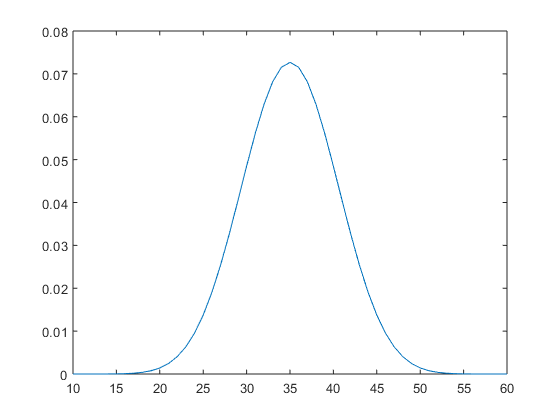

plot(x,sums_10); 

We now graph the probability, except this time for the *average *of the 10 dice. This is simply the probability above normalized by the average, or dividing by 10. 

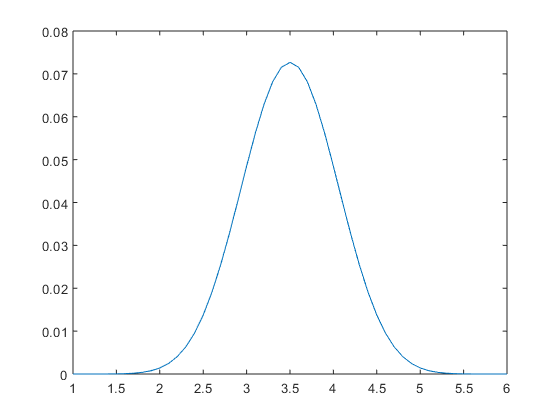

plot(x/10,sums_10); 

We can tell by inspection that this is clearly a standard Gaussian distribution - it is centered symmetrically about a mean with equal deviation on each side. We can also take the logarithm of this normal distribution - if this logarithmic scale follows a parabolic curve, then we will have double checked that this is a Gaussian distribution. 

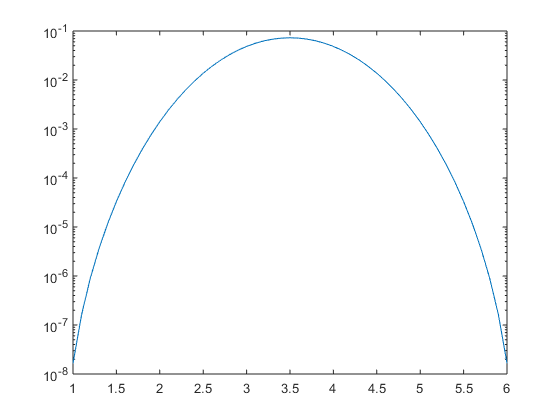

plot(x/10,sums_10); 
set(gca,'YScale','log'); 

As we can see, the probabilities of the averages of the rolls of 10 dice is clearly a Gaussian function. 

        5.   Show that the sum and average of an initially Gaussian distribution is in itself also a Gaussian. How does the standard deviation of the resulting sum or 

              average Gaussian change? This is a *hugely *important result. Discuss the implications for this and integrating a signal over time. 

The Gaussian distribution f(x) taking the two parameters mean and variance can be expressed as follows: 


$$f\left(x|\mu ,\sigma^2 \right)=\frac{1}{\sqrt{2\pi \sigma^2 }}e^{-\frac{{\left(x-\mu \right)}^2 }{2\sigma^2 }}$$


Regardless of our choices of mu and sigma, or the mean and variance, we will yield an f(x) of the form above. Adding two or more such functions, each with different mu and sigma, or even averaging multiple such functions, we will always have a resultant equation f(x) also of the form above. This implies that the sum or average of any number of Gaussian functions is also a Gaussian. Moreover, taking the logarithm of an f(x) of an *n *number of Gaussians simply results in adding *n *total parabolas, which in itself will always be a parabola of some form. This is additionally verification that the sum or average of an *n *number of Gaussian distributions is always a Gaussian. We can see from the f(x) equation that summing or averaging multiple f(x) will yield a proportional stretching or shrinking of the standard deviation. Thus, adding Gaussian functions together will cause the new variance, or square of the standard deviation, to be equal to the sum of the previous variances. This is crucial to the analysis of signals over time - if we are analyzing a normally distributed signal over a long time, then the standard deviation of this new distribution will eventually stretch out until the signal becomes increasingly homogenized and difficult to analyze. 